# How to extract ROI-data from 3D brain data?

% Load PET Image and Atlas:

%    Load the PET image header and data.
%    Load the brain atlas and its unique values to identify regions of interest (ROIs).

% Load ROI Information:

%    Load ROI information from a CSV file, including ROI indices and names.

% Extract BP for Right Insula:

%    Identify the ROI ID for the right insula and extract its BP data.
%    Visualize the BP data as a histogram and calculate the mean BP for the right insula.

% Extract BP for All ROIs:

%    Create a loop to extract BP data for each ROI one at a time.
%    Calculate the mean BP for each ROI and store the results.

% Organize ROI Data:

%    Combine the BP values with ROI names into a table for analysis.

## file processing


% descriptions
currentDir = pwd;

fileInput = 'wsrpet_nrm2018baseline1_bfsrtm_BP.nii';

fileAtlas_input = 'aal2_atlas.nii'

fileAtlas_input = 'aal2_atlas.nii'

fileAtlas_roi = 'aal2_atlas_roi_information.csv'

fileAtlas_roi = 'aal2_atlas_roi_information.csv'


% input data
dataFolder = fullfile(currentDir, '..', '..', '..', '..', 'data', 'health', 'pet', ...
    '1_session_neuroimaging_basics', 'nii_data');

inputDataPath = fullfile(dataFolder, fileInput);

% atlas data
atlasFolder = fullfile(currentDir, 'data', 'atlasses');

atlasDataPath_input = fullfile(atlasFolder, fileAtlas_input);
atlasDataPath_roi   = fullfile(atlasFolder, fileAtlas_roi);

disp(inputDataPath);

C:\Users\marku\OneDrive\Documents\MATLAB\healthcare\brain\main\..\..\..\..\data\health\pet\1_session_neuroimaging_basics\nii_data\wsrpet_nrm2018baseline1_bfsrtm_BP.nii


disp(atlasFolder);

C:\Users\marku\OneDrive\Documents\MATLAB\healthcare\brain\main\data\atlasses


## Load the header of a PET image using spm_vol function (PATH).


V_pet = spm_vol(inputDataPath);
img_pet = spm_read_vols(V_pet);

% Load the header and image matrix of AAL2 atlas using spm_vol and spm_read_vols (PATH)
V_atlas = spm_vol(atlasDataPath_input);
atlas = spm_read_vols(V_atlas);

% Check how many unique values the AAL2 atlas contains.
unique(atlas) % Unique index for each ROI but what are these ROIs?

ans =            0
        2001
        2002
        2101
        2102
        2201
        2202
        2301
        2302
        2311


## Load the atlas ROI information using readtable (PATH)

% This includes ROI indices and names

roi_info = readtable(atlasDataPath_roi);
roi_id = roi_info.roi_id; 
roi_name = roi_info.roi_name;

disp (roi_name)

    {'Precentral_L'        }
    {'Precentral_R'        }
    {'Frontal_Sup_2_L'     }
    {'Frontal_Sup_2_R'     }
    {'Frontal_Mid_2_L'     }
    {'Frontal_Mid_2_R'     }
    {'Frontal_Inf_Oper_L'  }
    {'Frontal_Inf_Oper_R'  }
    {'Frontal_Inf_Tri_L'   }
    {'Frontal_Inf_Tri_R'   }
    {'Frontal_Inf_Orb_2_L' }
    {'Frontal_Inf_Orb_2_R' }
    {'Rolandic_Oper_L'     }
    {'Rolandic_Oper_R'     }
    {'Supp_Motor_Area_L'   }
    {'Supp_Motor_Area_R'   }
    {'Olfactory_L'         }
    {'Olfactory_R'         }
    {'Frontal_Sup_Medial_L'}
    {'Frontal_Sup_Medial_R'}
    {'Frontal_Med_Orb_L'   }
    {'Frontal_Med_Orb_R'   }
    {'Rectus_L'            }
    {'Rectus_R'            }
    {'OFCmed_L'            }
    {'OFCmed_R'            }
    {'OFCant_L'            }
    {'OFCant_R'            }
    {'OFCpost_L'           }
    {'OFCpost_R'           }
    {'OFClat_L'            }
    {'OFClat_R'            }
    {'Insula_L'            }
    {'Insula_R'            }
    {'Cingulat

## Extract the mean BP value for right insula (Insula_R)

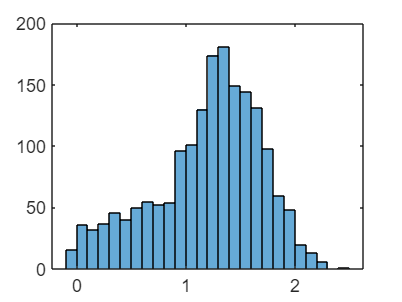

% steps: 

%   * Find the id for right insula
%   * Select only voxels where the has the id for right insula
%   * Visualize BPs from right insula as a histogram
%   * Take the mean as the representative BP estimate for insula 
%     (although the BP distribution was not excatly normal)

insula_id = roi_id(strcmp(roi_name,'Insula_R')); 
insula_data = img_pet(atlas == insula_id); 
histogram(insula_data); 

insula_BP = mean(insula_data); 

disp(insula_BP)

    1.1992



## Next extract the mean BP value for each AAL2 ROI.


% Create a for loop to extract the data for ROIs one at a time
% steps:

%   * Initialize a column vector where to store the regional mean BP values
%   * from 1 to the number of ROIs
%   * The ROI to extract
%   * Extract the ROI data
%   * Store the mean BP to the right place in the roi_bp vector

roi_bp = zeros(size(roi_id,1),1);
for I = 1:size(roi_id,1) 
    id = roi_id(I); 
    roi_data = img_pet(atlas == id); 
    roi_bp(I) = mean(roi_data); 
end

disp(roi_bp)

    0.2875
    0.2219
    0.4706
    0.4740
    0.4433
    0.4947
    0.5424
    0.5017
    0.4570
    0.3813
    0.5777
    0.4545
    0.7669
    0.6691
    0.3865
    0.3561
    1.5631
    1.4284
    0.6081
    0.6233
    0.9107
    0.9491
    1.1256
    1.1335
    0.6635
    0.5767
    0.3191
    0.2448
    0.8859
    0.8376
    0.3460
    0.0439
    1.1600
    1.1992
    1.2847
    1.0586
    0.7176
    0.6999
    0.2923
    0.1231
    0.6870
    0.6265
    0.9911
    1.2498
    1.0869
    0.8959
    0.3523
    0.3322
    0.2059
    0.2279
    0.3697
    0.2717
    0.1186
    0.1583
    0.2991
    0.2115
    0.2936
    0.1820
    0.7885
    0.7627
    0.2081
    0.1796
    0.1364
    0.0898
    0.3068
    0.3060
    0.3369
    0.3425
    0.3468
    0.2916
    0.3248
    0.3357
    0.1357
    0.1316
    0.2034
    0.2713
    0.5284
    0.4482
    0.4678
    0.4151
    0.0462
    0.0540
    0.9763
    0.8113
    0.8063
    0.6083
    1.0073
    0.8358
    0.6816
    0.5507
    0.8190

## Catenate BP and ROI name columns


roi_bp = array2table(roi_bp);
roi_bp.name = roi_name;

disp(roi_bp)

     roi_bp                name          
    _________    ________________________

      0.28753    {'Precentral_L'        }
      0.22193    {'Precentral_R'        }
      0.47058    {'Frontal_Sup_2_L'     }
      0.47399    {'Frontal_Sup_2_R'     }
      0.44334    {'Frontal_Mid_2_L'     }
       0.4947    {'Frontal_Mid_2_R'     }
      0.54239    {'Frontal_Inf_Oper_L'  }
       0.5017    {'Frontal_Inf_Oper_R'  }
      0.45695    {'Frontal_Inf_Tri_L'   }
      0.38128    {'Frontal_Inf_Tri_R'   }
      0.57766    {'Frontal_Inf_Orb_2_L' }
      0.45454    {'Frontal_Inf_Orb_2_R' }
      0.76685    {'Rolandic_Oper_L'     }
      0.66912    {'Rolandic_Oper_R'     }
      0.38645    {'Supp_Motor_Area_L'   }
      0.35606    {'Supp_Motor_Area_R'   }
       1.5631    {'Olfactory_L'         }
       1.4284    {'Olfactory_R'         }
      0.60813    {'Frontal_Sup_Medial_L'}
       0.6233    {'Frontal_Sup_Medial_R'}
      0

## As functions

clear;

% descriptions
currentDir = pwd;

fileInput = 'wsrpet_nrm2018baseline1_bfsrtm_BP.nii';

fileAtlas_input = 'aal2_atlas.nii'

fileAtlas_input = 'aal2_atlas.nii'

fileAtlas_roi = 'aal2_atlas_roi_information.csv'

fileAtlas_roi = 'aal2_atlas_roi_information.csv'


% input data
dataFolder = fullfile(currentDir, '..', '..', '..', '..', 'data', 'health', 'pet', ...
    '1_session_neuroimaging_basics', 'nii_data');

inputDataPath = fullfile(dataFolder, fileInput);

% atlas data
atlasFolder = fullfile(currentDir, 'data', 'atlasses');

atlasDataPath_input = fullfile(atlasFolder, fileAtlas_input);
atlasDataPath_roi   = fullfile(atlasFolder, fileAtlas_roi);

[roi_bp, insula_id, insula_data, insula_BP] = RoiDataOnPet(inputDataPath, ... 
    atlasDataPath_input, atlasDataPath_roi);

disp (roi_bp);

     roi_bp                name          
    _________    ________________________

      0.28753    {'Precentral_L'        }
      0.22193    {'Precentral_R'        }
      0.47058    {'Frontal_Sup_2_L'     }
      0.47399    {'Frontal_Sup_2_R'     }
      0.44334    {'Frontal_Mid_2_L'     }
       0.4947    {'Frontal_Mid_2_R'     }
      0.54239    {'Frontal_Inf_Oper_L'  }
       0.5017    {'Frontal_Inf_Oper_R'  }
      0.45695    {'Frontal_Inf_Tri_L'   }
      0.38128    {'Frontal_Inf_Tri_R'   }
      0.57766    {'Frontal_Inf_Orb_2_L' }
      0.45454    {'Frontal_Inf_Orb_2_R' }
      0.76685    {'Rolandic_Oper_L'     }
      0.66912    {'Rolandic_Oper_R'     }
      0.38645    {'Supp_Motor_Area_L'   }
      0.35606    {'Supp_Motor_Area_R'   }
       1.5631    {'Olfactory_L'         }
       1.4284    {'Olfactory_R'         }
      0.60813    {'Frontal_Sup_Medial_L'}
       0.6233    {'Frontal_Sup_Medial_R'}
      0

histogram(insula_data);